## Neuron-Count Publication Figures

Compare saved low-rank Lorenz, Yacht, and breast-cancer tests at 1k, 2k, 4k, 8k, 16k, and 32k neurons. The script loads saved full-test analyses only.

clear; clc; close all;
repo_root = project_root();
addpath(fullfile(repo_root, 'shared', 'matlab'), '-begin');
add_project_paths(repo_root);

## ---------------- Data Selection ----------------

Each count uses its newest saved Lorenz analysis. The example plots use the single saved network seed and the first test initial condition. The WD swarm uses one point per saved test IC, averaged across the three Lorenz phase planes.

neuron_counts = [1000 2000 4000 8000 16000 32000];
example_seed_index = 1;
required_test_ic_count = 5;
require_complete_test_ics = true;

load_opts = struct();
load_opts.neuron_counts = neuron_counts;
load_opts.example_seed_index = example_seed_index;
load_opts.network_seed_index = 1;
load_opts.required_test_ic_count = required_test_ic_count;
load_opts.require_complete_test_ics = require_complete_test_ics;
lorenz_sweep = load_lorenz_neuron_sweep_publication_data(load_opts);
bc_sweep = load_static_neuron_sweep_publication_data('classification_BC', load_opts);
yacht_sweep = load_static_neuron_sweep_publication_data('regression_yacht', load_opts);

## ---------------- Publication Plot Controls ----------------

Phase portraits use this fraction of each saved post-warmup trajectory. Set to 1 for the full saved test.

plot_opts = struct();
plot_opts.phase_tfrac = 1;
plot_opts.phase_stride = 1;
plot_opts.classification_sweep = bc_sweep;
plot_opts.regression_sweep = yacht_sweep;

% Layout and visual style
plot_opts.left_margin = 0.06;
plot_opts.right_margin = 0.03;
plot_opts.bottom_margin = 0.08;
plot_opts.top_margin = 0.10;
plot_opts.hgap = 0.025;
plot_opts.vgap = 0.08;

% Combined-figure layout
plot_opts.combined_left_margin = 0.07;
plot_opts.combined_right_margin = 0.03;
plot_opts.combined_bottom_margin = 0.07;
plot_opts.combined_top_margin = 0.08;
plot_opts.combined_hgap = 0.02;
plot_opts.combined_vgap = 0.035;

% Typography, markers, lines, and colours
plot_opts.fs_ticks = 10;
plot_opts.fs_labels = 10;
plot_opts.fs_titles = 12;
plot_opts.figure_title_font_size = 14;
plot_opts.combined_figure_title_font_size = 16;
plot_opts.panel_title_font_size = 12;
plot_opts.legend_font_size = 9;
plot_opts.combined_row_label_font_size = 8;
plot_opts.combined_row_labels_enable = false;
plot_opts.phase_line_width = 0.7;
plot_opts.phase_true_inset_enable = true;
plot_opts.phase_true_inset_width_fraction = 0.32;
plot_opts.phase_true_inset_height_fraction = 0.32;
plot_opts.phase_true_inset_left_offset_fraction = 0.05;
plot_opts.phase_true_inset_line_width = 0.6;
plot_opts.swarm_marker_size = 34;
plot_opts.swarm_mean_marker_size = 60;
plot_opts.metric_mean_marker_size = 26;
% One size for every scatter marker in the four lower combined-figure panels.
plot_opts.bottom_panel_marker_size = 24;
plot_opts.swarm_point_color = [0 0 0];
plot_opts.swarm_point_alpha = 1;
plot_opts.swarm_mean_color = [0 0.4470 0.7410];
plot_opts.swarm_errorbar_line_width = 2.5;
plot_opts.swarm_errorbar_cap_size = 8;
plot_opts.wd_legend_enable = true;
plot_opts.wd_ic_legend_label = 'Test IC';
plot_opts.wd_mean_legend_label = 'Mean \pm SD';
plot_opts.wd_legend_font_size = 7;
plot_opts.wd_legend_background_color = [0.90 0.95 1.00];
plot_opts.wd_legend_edge_color = [0 0.4470 0.7410];
plot_opts.wd_legend_line_width = 2;
plot_opts.wd_y_scale = 'log';
plot_opts.wd_legend_location = 'northeast';
plot_opts.swarm_width = 0.22;
plot_opts.accuracy_y_limits = [0 100];
plot_opts.pearson_y_limits = [-1 1];
plot_opts.rmse_y_limits = [0 10];
plot_opts.network_color = [0 0 0];
plot_opts.true_color = [0.8660 0.3290 0.0000];

% Titles, labels, and legend text
plot_opts.condition_labels = {'1k', '2k', '4k', '8k', '16k', '32k'};
plot_opts.phase_figure_title = '';
plot_opts.wd_figure_title = '';
plot_opts.accuracy_figure_title = '';
plot_opts.pearson_figure_title = 'Yacht Pearson r';
plot_opts.rmse_figure_title = 'Yacht RMSE';
% A single space deliberately suppresses the renderer's default title.
plot_opts.combined_figure_title = ' ';
plot_opts.combined_wd_title = 'Lorenz WD';
plot_opts.combined_phase_title = 'Lorenz phase portraits';
plot_opts.combined_phase_title_font_size = 12;
plot_opts.combined_accuracy_title = 'Breast-cancer accuracy';
plot_opts.combined_pearson_title = 'Yacht Pearson r';
plot_opts.combined_rmse_title = 'Yacht RMSE';
plot_opts.phase_x_label = 'x_1';
plot_opts.phase_y_label = 'x_2';
plot_opts.wd_x_label = 'Number of neurons';
plot_opts.wd_y_label = 'Phase-portrait WD';
plot_opts.metric_x_label = 'Number of neurons';
plot_opts.accuracy_y_label = 'Accuracy (%)';
plot_opts.pearson_y_label = 'Pearson r';
plot_opts.rmse_y_label = 'RMSE';
plot_opts.network_legend_label = 'Network output';
plot_opts.true_legend_label = 'True system';
plot_opts.legend_location = 'southwest';
% Optional normalized [left bottom width height] overrides. Leave [] to use
% the current footer positions calculated from the figure layout.
plot_opts.separate_network_true_legend_position = [];
plot_opts.combined_network_true_legend_enable = false;
plot_opts.combined_phase_y = 0.66;
plot_opts.combined_phase_height = 0.16;
plot_opts.combined_metric_axes_positions = {[0.10 0.40 0.34 0.16], [0.58 0.40 0.34 0.16], ...
    [0.10 0.10 0.34 0.16], [0.58 0.10 0.34 0.16]};
plot_opts.combined_panel_letter_font_size = 18;

## ---------------- Export Controls ----------------

Each figure is exported after plotting. Edit these settings as needed.

export_enable = true;
export_dir = fullfile(repo_root, 'shared', 'plotting', 'publication_figures', 'generated_neuron_sweep_figures');
export_dpi = 500;
export_format = 'png';

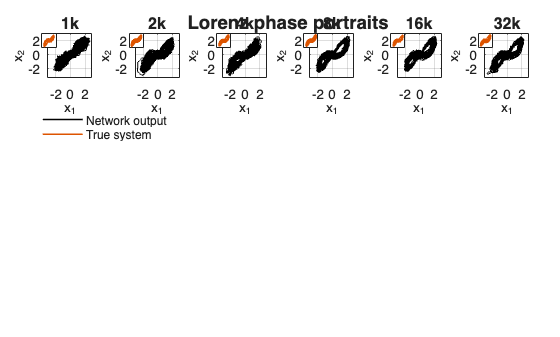

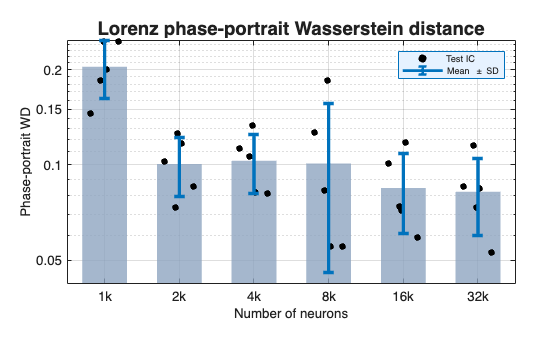

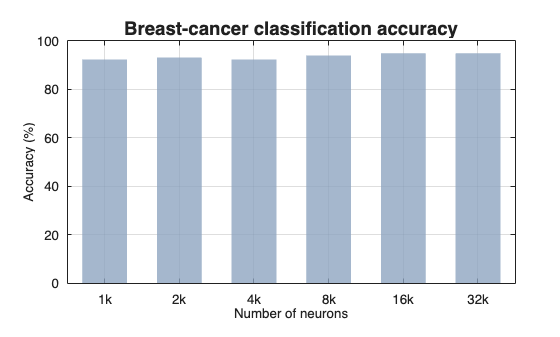

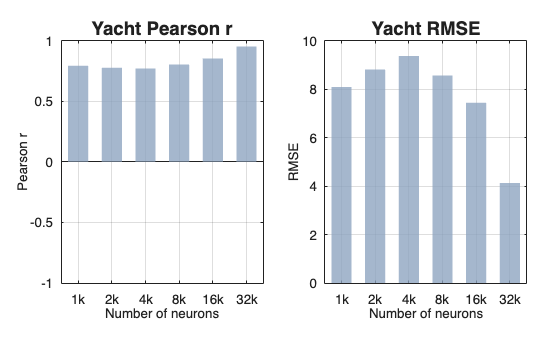

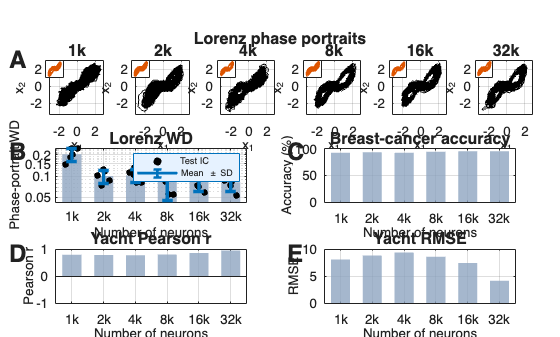

figures = plot_lorenz_neuron_sweep_publication(lorenz_sweep, plot_opts);
if export_enable
    export_neuron_sweep_figures(figures, export_dir, export_format, export_dpi);
end

fprintf('Displayed Lorenz phase/WD, breast-cancer accuracy, Yacht regression, and combined neuron-sweep figures.\n');

Displayed Lorenz phase/WD, breast-cancer accuracy, Yacht regression, and combined neuron-sweep figures.



function export_neuron_sweep_figures(figures, output_dir, format, dpi)
if exist(output_dir, 'dir') ~= 7, mkdir(output_dir); end
names = fieldnames(figures);
for ii = 1:numel(names)
    file = fullfile(output_dir, ['neuron_sweep_' names{ii} '.' lower(format)]);
    switch lower(format)
        case 'png'
            print(figures.(names{ii}), file, '-dpng', sprintf('-r%d', dpi));
        case 'svg'
            print(figures.(names{ii}), file, '-dsvg');
        otherwise
            error('plot_lorenz_neuron_count_publication:unsupportedExportFormat', ...
                'Supported export formats are png and svg.');
    end
end
end